# UBC CPSC  302 Num Comp for Alg Problems, 2019W

# Assignment 3

### by j0k0b #42039157

*Tips: Use the tips from Assignment 1 to get the most credit possible on this and future assignments.  Replace the [Preferred Name or CS-ID] and [Student Number] above. *

## Acknowledgments

You are welcome to work with other students on this assignment, but everything in this file must clearly be your own original work.  Complete the following section to recognize your collaborators on this assignment.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin acknowledgments }~~~~~~~~~~~~~~~~~~~~~}$$


Thanks to [name or CS-ID] for [their contribution].

Thanks to [name or CS-ID] for [their contribution].

Other than the contributions above, this work is my own.

— [Your preferred name or CS-ID]


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End acknowledgments }$$


## Question 1 Comparison of methods

For $x>0$ consider the problem

                        
$$f(x)=x+\ln(x)=0.$$


There is exactly one root $f(x^*)=0$, $0<x^*<\infty$.

## Question 1.1

Write MATLAB code to plot a graph of the function on the interval $[0.1,\; 1]$.  Include the "`grid on`" or other commands to show approximately where the root is.  

### Answer 1.1 [2 marks]

Enter your solution in the space below.

*Tips: Insert clear, functioning MATLAB code as necessary.  Run your code to produce output (data and/or figures) before saving this MLX file and exporting it as a PDF.  Every plot should be titled, contain a legend, contain labeled axes, and use a unique colour, line style and/or marker for each dataset.*

*Adjust the size (drag corners) of inserted images so they don't get cropped when exporting to PDF.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


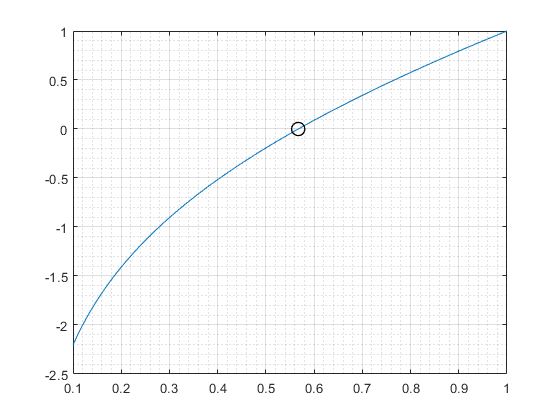

x = linspace(0.1, 1.0, 100); % we are given the interval b/w [0.1, 1.0]
f_x = x + log(x); % f(x) = x + ln(x) = 0
plot(x,f_x) % root between 0.5 and 0.6
hold on
plot(0.567,0,'ko','MarkerSize',10,'LineWidth',1); % x = -ln(x); e^x = 1/x
grid on % shows grid to clarify root location
grid minor % more significant number of grids


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Further instructions for Question 1

For each of the iterative methods below:

- Use $|x_k - x_{k-1} | < 10^{-10}$ as a convergence criterion.

- Store the iterates $x_k,\ k=1,2,\ldots$ in a variable for later comparison with other methods.

## Question 1.2 Bisection method

Use the Intermediate Value Theorem to argue that the bisection method will converge to the root from the initial interval $[0.5,\; 0.6]$.  

Apply the bisect function (code provided below) using the instructions above to find the root. Demonstrate that you've chosen a tolerance that satisfies the convergence criterion above.

### Answer 1.2 Bisection method [2 marks]

Enter your solution in the space below.

*Tips: Add your function to the *My functions* section below.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


p = bisect('fx', 0.5, 0.6, fx(0.1), fx(1.0), 1.e-10);
table(p) % the table depicts that it does converge to 0.5671

ans = 29×1 table
       p   
    _______

       0.55
      0.575
     0.5625
    0.56875
    0.56563
    0.56719
    0.56641
     0.5668
    0.56699
    0.56709
    0.56714
    0.56716
    0.56715
    0.56714
    0.56714
    0.56714



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1.3 Fixed point iteration

Write MATLAB code for finding the root, using a linearly convergent fixed point iteration, with $x_0 = 0.5$.  Show that the conditions of the Fixed Point Theorem (for the function $g$ you have selected) are satisfied.  (You are encouraged to write your code as a function below – for later reuse in Question 2 – just indicate so to the reader so they can find it.)

Apply your fixed point iteration using the instructions above to find the root.

### Answer 1.3 Fixed point iteration [2 marks]

Enter your solution in the space below.

*Tips: You may use and modify code from lesson *[Fixed point iteration](https://canvas.ubc.ca/courses/40496/files/5463503/download?wrap=1)* Section 6.2 in your answer.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1.4 Newton's method

Write MATLAB code for finding the root, using Newton's method, with $x_0 = 0.5$.  (You are encouraged to write your code as a function below – for later reuse in Question 2 – just indicate so to the reader so they can find it.)

Apply your Newton's method using the instructions above to find the root.

### Answer 1.4 Newton's method [2 marks]

Enter your solution in the space below.

*Tips: You may use and modify code from lesson *[Newton's method and variants](https://canvas.ubc.ca/courses/40496/files/5489808/download?wrap=1)* Section 4.2 in your answer.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1.5 Secant method

Write MATLAB code for finding the root, using the secant method, with $x_0 = 0.5$ and $x_1=0.6$.  (You are encouraged to write your code as a function below – for later reuse in Question 2 – just indicate so to the reader so they can find it.)

Apply your secant method using the instructions above to find the root.

### Answer 1.5 Secant method [2 marks]

Enter your solution in the space below.

*Tips: You may use and modify code from lesson *[Newton's method and variants](https://canvas.ubc.ca/courses/40496/files/5489808/download?wrap=1)* Section 8 in your answer.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1.6 Explain

Plot the iterates for all of your above methods (§1.2–1.5) on one graph in order to show their progression. Explain the convergence behavior of each and how it matches theoretical expectations.

### Answer 1.6 Explain [2 marks]

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2 Find the global minimum

Write a MATLAB program to minimize this smooth, scalar function in one variable 

                        
$$\phi(x) = \cos(x) \left( \frac{1}{2} - x e^{-x^2} \right)$$


over the interval $[-25,\; 25]$.

Your program should:

- First find and display all critical points, i.e., zeros of $\phi'(x)$.

- Then it should determine which of these correspond to a local minimum by checking the sign of $\phi''$, and display the local minimum points.

- Finally, it should determine the global minimum point(s), value and arguments, by minimizing over the local minimum values.

Briefly justify your choice of algorithm(s) to find the critical points.  (I.e. what algorithmic properties are most/least important to you for this problem and how does your choice reflect your priorities?)

(If you coded any of your algorithms for Question 1 as functions, you are welcome to use them here as part of your solution.)

### Answer 2 Find the global minimum [8 marks]

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## 3 My functions

MATLAB requires all functions to be at the [end of the script](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html).  Enter functions you wrote for this assignment in the space below.

*Tips: You only need to complete this section if you developed and used your own MATLAB function(s) in your code above.  If you do define your own functions, organize your code; use indenting and reasonable variables (e.g. no unused variables or ambiguous names).  Document your code clearly and effectively with comments (*`% This is a comment`*).  Note the specific purpose of each function; indicate input requirements and output results.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin functions}~~~~~~~~~~~~~~~~~~~~~}$$


function f = fx(x)
f = x + log(x);
end


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End functions}$$


## 4 Provided functions

Additional utility functions are provided here.  You should not need to modify these functions and may use them "as-is" in your code.

## 4.1 bisect function

function p = bisect(func, a,b, fa,fb, atol)
%
% function p = bisect(func,a,b,fa,fb,atol)
%
% Assuming fa = func(a), fb = func(b), and fa * fb < 0,
% there is a value root in (a,b) such that func(root) = 0.
% This function returns in p the bisection iterates such that
% | p(end) - root | < atol
% and in length(p) the number of iterations required. Bisection root-finding method
% modified from lesson "Nonlinear equations in one variable.  Bisection method"
% and [AG Book] Section 3.2.
if (a >= b) || (fa*fb >= 0) || (atol <= 0)
    disp('something wrong with the input: quitting');
    p = NaN;
    return;
end
n = ceil( log2(b-a) - log2(2*atol) );
p = zeros(n,1); % pre-allocate storage array of midpoints, p[1..n]
for k=1:n
    p(k) = (a+b)/2;
    fp = feval(func,p(k));
    if fa * fp < 0
        b = p(k);
        %fb = fp;    % value assigned to fb here is unused
    else
        a = p(k);
        fa = fp;
    end
end
p(k) = (a+b)/2;
end % bisect